# Problam1 - Practic

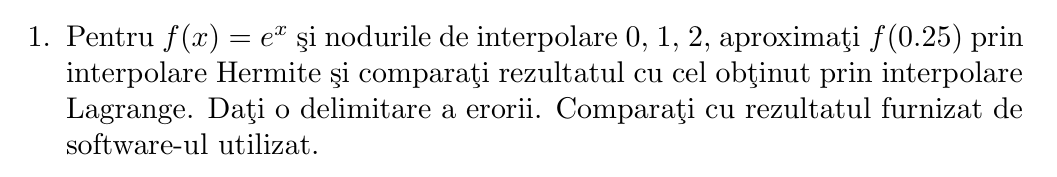

% PB1
function [p_val, coef, z] = interpolareHermite(x, f, df, x_eval)
% INTERPOLAREHERMITE - Interpolare Hermite cu noduri duble (forma Newton)
%
% INPUT:
%   x       - vector cu nodurile xi (lungime n)
%   f       - valorile functiei f(xi)
%   df      - valorile derivatei f'(xi)
%   x_eval  - punctele in care se evalueaza polinomul
%
% OUTPUT:
%   p_val   - valorile interpolate in punctele x_eval
%   coef    - coeficientii Newton ai polinomului Hermite
%   z       - vectorul de noduri extinse (cu dubluri)

    n = length(x);        % numarul de noduri initiale
    m = 2 * n;            % numarul de linii in tabela (fiecare nod apare de 2 ori)
    
    z = zeros(1, m);      % vectorul de noduri extinse: z_0, z_1, ..., z_{2n-1}
    Q = zeros(m, m);      % tabela Hermite de diferente divizate

    % P1, P2 
    for i = 1:n
        z(2*i - 1) = x(i);               
        z(2*i)     = x(i);              
        
        Q(2*i - 1, 1) = f(i);            
        Q(2*i,     1) = f(i);          
        
        Q(2*i,     2) = df(i);           

        % P3 - Daca nu suntem pe primul nod, calculam Q_{2i,1} 
        if i ~= 1
            Q(2*i - 1, 2) = (Q(2*i - 1, 1) - Q(2*i - 2, 1)) / ...
                           (z(2*i - 1) - z(2*i - 2));
        end
    end

    % P4 - Completam tabela Hermite (diferente divizate de ordin superior) 
    for i = 3:m
        for j = 3:i
            Q(i,j) = (Q(i,j-1) - Q(i-1,j-1)) / (z(i) - z(i-j+1));
        end
    end

    % P5 - Extragem coeficientii de pe diagonala
    coef = diag(Q);  % coeficientii din forma Newton

    % Evaluare polinom Hermite in punctele x_eval 
    p_val = zeros(size(x_eval));  % vector rezultat

    for k = 1:length(x_eval)
        val = coef(1);             % pornim cu primul coeficient
        produs = 1;

        for j = 2:m
            produs = produs * (x_eval(k) - z(j-1));
            val = val + coef(j) * produs;
        end

        p_val(k) = val;
    end
end

%PB1 - lab7
function [p_val, p_expr] = lagrangeInterpolation(x_nodes, y_nodes, x_eval)
% INPUT:
%   x_nodes  - vectorul nodurilor de interpolare 
%   y_nodes  - vectorul valorilor functiei in noduri 
%   x_eval   - vectorul punctelor in care se evalueaza polinomul
%
% OUTPUT:
%   p_val    - valorile numerice ale polinomului in punctele x_eval
%   p_expr   - expresia simbolica a polinomului
 
    % Numarul de noduri
    n = length(x_nodes);

    % Asiguram ca x_eval este coloana
    x_eval = x_eval(:);

    % Initializam vectorul rezultat
    p_val = zeros(size(x_eval));

    % Initializare variabila simbolica si polinom simbolic
    syms x;
    p_expr = 0;

    % Construim expresia simbolica si evaluam numeric
    for i = 1:n
        % Initializare L_i(x)
        L_i = 1;
        for j = 1:n
            if j ~= i
                L_i = L_i * (x - x_nodes(j)) / (x_nodes(i) - x_nodes(j));
            end
        end
        % Adunam termenul y_i * L_i(x)
        p_expr = p_expr + y_nodes(i) * L_i;
    end

    % Evaluam numeric in punctele dorite
    for k = 1:length(x_eval)
        p_val(k) = double(subs(p_expr, x, x_eval(k)));
    end

    % Simplificam 
    p_expr = expand(p_expr);  % dezvoltare
end

f_original = @(x) exp(x);
df_original = @(x) exp(x);

x = [0, 1, 2];
f = f_original(x);
df = df_original(x);

x_eval = 0.25;
[Hp_val, coef, z] = interpolareHermite(x, f, df, x_eval);

[Lp_val, p_expr] = lagrangeInterpolation(x, f, x_eval);

real_val = exp(0.25);  % ≈ 1.2840254
err_hermite = abs(Hp_val - real_val);
err_lagrange = abs(Lp_val - real_val);

max_f6 = exp(2);  % maximul derivatelor in [0,2]
factorial6 = factorial(6);
prod_term = (x_eval - 0)^2 * (x_eval - 1)^2 * (x_eval - 2)^2;

error_bound = (max_f6 / factorial6) * prod_term;

fprintf('f(0.25) exact        = %.7f\n', real_val);

f(0.25) exact        = 1.2840254


fprintf('Interpolare Hermite  = %.7f, eroare = %.6e\n', Hp_val, err_hermite);

Interpolare Hermite  = 1.2836451, eroare = 3.803175e-04


fprintf('Interpolare Lagrange = %.7f, eroare = %.6e\n', Lp_val, err_lagrange);

Interpolare Lagrange = 1.1527743, eroare = 1.312511e-01


fprintf('Delimitare teoretica a erorii Hermite: %.6e\n', error_bound);

Delimitare teoretica a erorii Hermite: 1.104931e-03
